#### Basis Generation


% clear;
tic;
% N as atoms number, M as sites number
N_Sites = 8;
N_atoms = 4;


#### Basis Generation


% Accuracy used to search the Tags
Accuracy = 1e3 * eps;

Sz_Conservation = 1;

if Sz_Conservation == 1
    % Fermionic fock space for spin conserved space
    % Spin conserved, select the number of spin up
    % N_spin_up = 11;
    N_spin_up = ceil(N_atoms / 2);
    N_spin_down = N_atoms - N_spin_up;
    Dimension = nchoosek(N_Sites, N_spin_up) * nchoosek(N_Sites, N_spin_down);
    % Initialize the basis through cell
    % Since spin conserved, we can 
    Basis_up = Basis_Conserved(N_Sites, N_spin_up);
    Basis_down = Basis_Conserved(N_Sites, N_spin_down);

    Basis = table2array(combinations(Basis_down, Basis_up));
    % Basis = join(Basis,'');
    % Calculate the tag function for each basis
    Tags = bin2dec(join(Basis,''));
    [Tags, ind] = sort(Tags);
    Basis = Basis(ind,:);
else
    % Fermionic fock space for spin non conserved space
    Dimension = 0;
    for ii = max([0, N_atoms - N_Sites]):min(N_Sites,N_atoms)
        Dimension = Dimension + nchoosek(N_Sites, ii) * nchoosek(N_Sites, N_atoms - ii);
    end
    Basis = Basis_NonConserved(N_Sites, N_atoms);
    Tags = bin2dec(join(Basis,''));
    [Tags, ind] = sort(Tags);
    Basis = Basis(ind,:);
end

Setting up the Hamiltonian matrix


$$H=-t\sum_{\langle ij\rangle\sigma}(c_{i\sigma}^\dagger c_{j\sigma} +c_{j\sigma}^\dagger c_{i\sigma})+U\sum_{i}\hat{n}_{i\uparrow}\hat{n}_{i\downarrow}$$


% Interacting matrix
DoubleOccupied = (cell2mat(Basis(:,1)) - '0').*(cell2mat(Basis(:,2)) - '0'); 
H_interaction = spdiags(sum(DoubleOccupied, 2), 0, Dimension, Dimension);



% hopping matrix
col = zeros(1, (2*N_Sites+1) * Dimension);
row = zeros(1, (2*N_Sites+1) * Dimension);
val = zeros(1, (2*N_Sites+1) * Dimension);
Count = 1;


for ii = 1: Dimension
    % Spin conservation hopping, separate the spin up and spin down
    % start from spin up
    temp_hopping = nearest_neighbor_hopping(Basis{ii, 2});
    if iscell(temp_hopping)
        HoppingBasis = cellfun(@(s) [Basis{ii, 1}, s], temp_hopping, 'UniformOutput', false);
        [~, loc] = ismember(bin2dec(HoppingBasis), Tags);
        col(Count:Count+length(loc) - 1) = ii;
        row(Count:Count+length(loc) - 1) = loc';
        val(Count:Count+length(loc) - 1) = 1;
        Count = Count + length(loc);
    % else
    %     % Why I write the following 3 line?
    %     col(Count) = ii;
    %     row(Count) = ii;
    %     val(Count) = 0;
    %     Count = Count + 1;
    end

    % spin down hopping
    temp_hopping = nearest_neighbor_hopping(Basis{ii, 1});
    if iscell(temp_hopping)
        HoppingBasis = cellfun(@(s) [s, Basis{ii, 2}], temp_hopping, 'UniformOutput', false);
        [~, loc] = ismember(bin2dec(HoppingBasis), Tags);
        col(Count:Count+length(loc) - 1) = ii;
        row(Count:Count+length(loc) - 1) = loc';
        val(Count:Count+length(loc) - 1) = 1;
        Count = Count + length(loc);
    % else
    %     col(Count) = ii;
    %     row(Count) = ii;
    %     val(Count) = 0;
    %     Count = Count + 1;
    end
end

ind = max(find(col,1,'last'), find(row,1,'last'));
col = col(1:ind);
row = row(1:ind);
val = val(1:ind);
H_kinetic = sparse(row, col, val);
% clear col row val

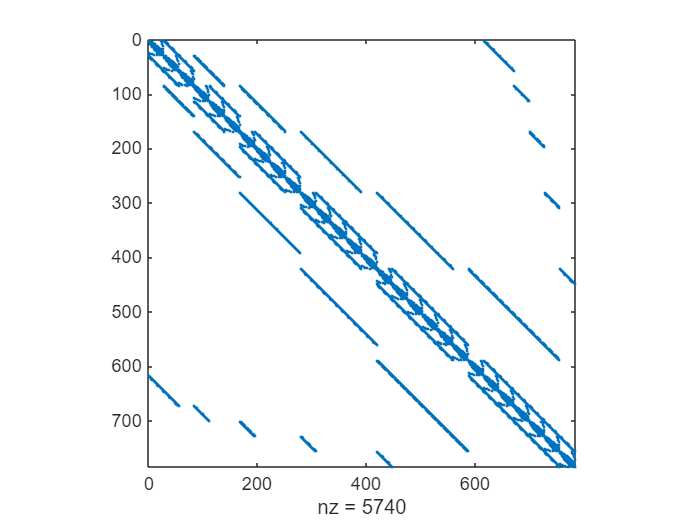

U = 6;
t = 1;

H = -t * H_kinetic + U * H_interaction;
spy(H)

% full(H)
toc;

历时 0.179180 秒。


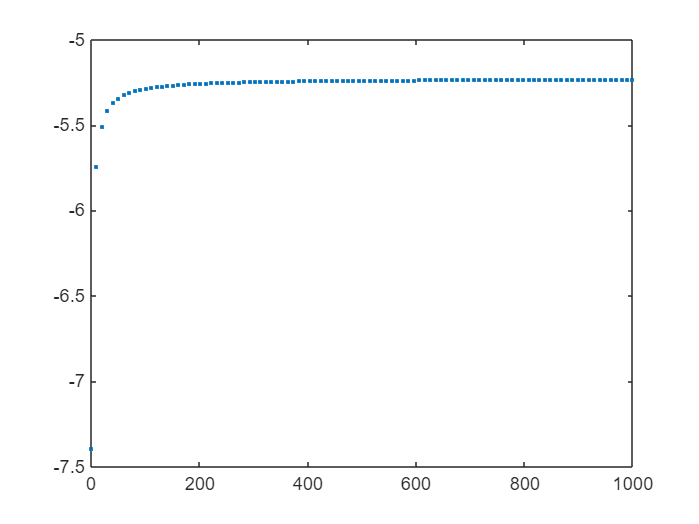


% [~, Eval] = eigs(H,20,'sr');
U = linspace(0, 1000, 100);
Eval = zeros(1, length(U));
for ii = 1:length(U)
    H = -t * H_kinetic + U(ii) * H_interaction;
    Eval(ii) = eigs(H, 1, 'sr');
end

% disp(num2str(Eval));
plot(U,Eval,'.')

% DOS_plot(Eval,100)


toc;

历时 0.722153 秒。








function Basis = Basis_Conserved(N_Sites, N_chosen_spin)


temp = zeros(1, N_Sites);
% Set the first basis as (1, 1, 0...)
temp(1:N_chosen_spin) = 1;
%---------------------------------------------------------------------------------
% The following method comes from
% https://stackoverflow.com/questions/69707949/generate-a-matrix-of-combinations-permutation-without-repetition-array-exceed

N = numel(temp); % number of elements in array
k = nnz(temp);   % number of non-zero elements in array

colidx = nchoosek(1:N, k);                  % column index for ones
rowidx = repmat( 1:size(colidx,1), k, 1 ).';  % row index for ones

Basis = zeros(size(colidx,1), N); % create output
Basis(rowidx(:) + size(Basis,1) * (colidx(:)-1) ) = 1;
%---------------------------------------------------------------------------------
Basis = join(compose('%d',Basis),'');
end





function Basis = Basis_NonConserved(N_Sites, N_atoms)

temp = zeros(1, 2 * N_Sites);
% Set the first basis as (N, 0, 0...)
temp(1:N_atoms) = 1;
%---------------------------------------------------------------------------------
% The following method comes from
% https://stackoverflow.com/questions/69707949/generate-a-matrix-of-combinations-permutation-without-repetition-array-exceed

N = numel(temp); % number of elements in array
k = nnz(temp);   % number of non-zero elements in array

colidx = nchoosek( 1:N, k );                  % column index for ones
rowidx = repmat( 1:size(colidx,1), k, 1 ).';  % row index for ones

Basis = zeros(size(colidx,1), N); % create output
Basis(rowidx(:) + size(Basis,1) * (colidx(:)-1) ) = 1;
%---------------------------------------------------------------------------------
Basis = join(compose('%d',Basis),'');

[Basis_up, Basis_down] = cellfun(@(s) deal(s(1:N_Sites), s(N_Sites+1:end)), Basis, 'UniformOutput', false);
Basis = [Basis_up, Basis_down];
end


function neighbors = nearest_neighbor_hopping(binary_str)
% Generated by deepseek
% 给出matlab命令，给定一组二进制字符串，给出其所有可能的最近邻跃迁得到的新的二进制字符串，
% 例如给定00110，其最近邻跃迁有为01010 ,00101，且有周期性边界条件，
% 即00001有00010和10000两种跃迁
% 不使用循环
    % 输入: binary_str - 二进制字符串，如 '00110'
    % 输出: neighbors - 所有最近邻跃迁得到的二进制字符串集合
    
    n = length(binary_str);
    binary_array = double(binary_str) - '0';  % 转换为数值数组
    if (sum(binary_array) == n) || (sum(binary_array) == 0)
        neighbors = false;
        return 
    end
    
    % 生成所有可能的交换位置对 (i,j)
    i = 1:n;
    j = mod(i, n) + 1;  % 周期性边界
    
    % 找出需要交换的位置 (相邻位不同的情况)
    swap_mask = (binary_array(i) ~= binary_array(j));
    i_swap = i(swap_mask);
    j_swap = j(swap_mask);
    
    % 一次性生成所有交换后的数组
    neighbor_arrays = repmat(binary_array, [sum(swap_mask), 1]);
    idx = sub2ind(size(neighbor_arrays), 1:sum(swap_mask), i_swap);
    jdx = sub2ind(size(neighbor_arrays), 1:sum(swap_mask), j_swap);
    
    % 交换i和j位的值
    temp = neighbor_arrays(idx);
    neighbor_arrays(idx) = neighbor_arrays(jdx);
    neighbor_arrays(jdx) = temp;
    
    % 转换回字符串, 去除因周期性边界条件导致的重复hopping
    neighbors = unique(cellstr(char(neighbor_arrays + '0')));
end

